addpath('./datos')
addpath('./funciones/')

% Cargo el fichero .wav
[xn fs_period] = audioread('test_period_70.wav');
%[xn fs_period] = audioread('Afonso_8khz.wav');
xn=xn';

**FILTRO DE PREÉNFASIS:**

% FILTRO DE PREENFASIS --------------------------------
bk=[1 -0.86];
Hp=filter(bk,1,xn);
sn=Hp;
% plot(sn(1:250)),xlabel('n'),ylabel('s(n)'),grid;
% -----------------------------------------------------

% Definición e inicialización de variables
p=10;
Lframe=160; 
Lsubframe=Lframe/4; 
start_slice_subframe=1;
stop_slice_subframe=Lsubframe;
start_slice_frame=1;
stop_slice_frame=Lframe;
z = [];
zi = [];
dn = [];
E = [];
dp=zeros(1,120);
drp=zeros(1,120);
dr = [];
z2 = [];
sr = [];

**ANÁLISIS Y RECONSTRUCCIÓN :**

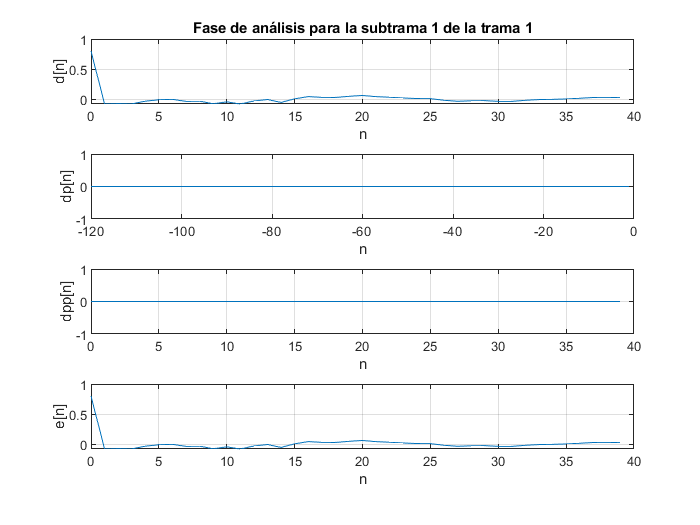

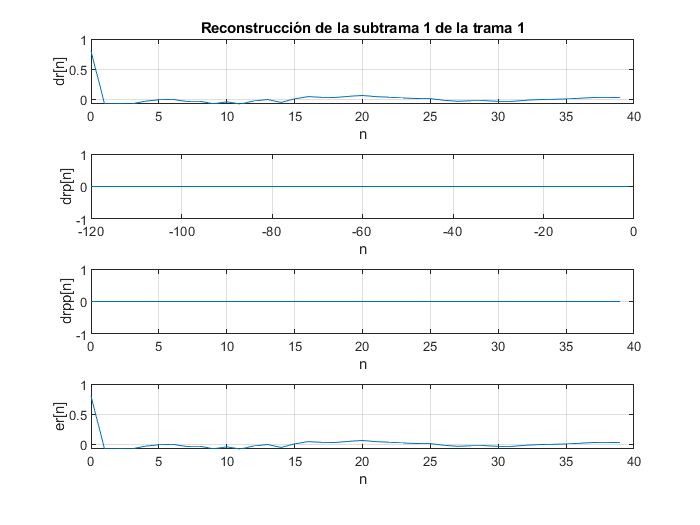

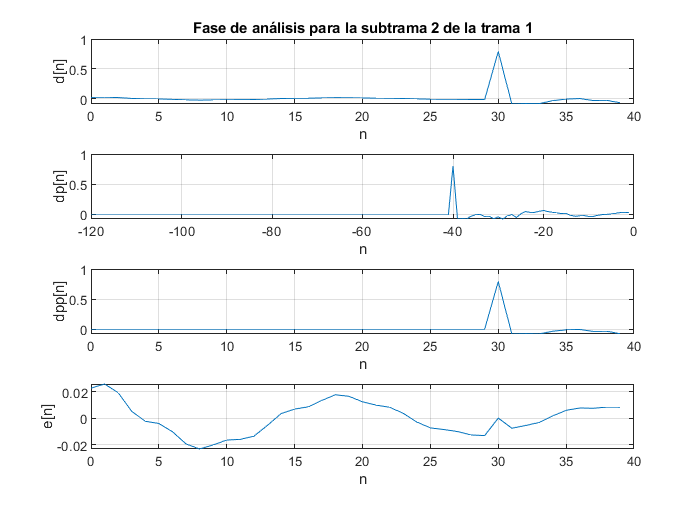

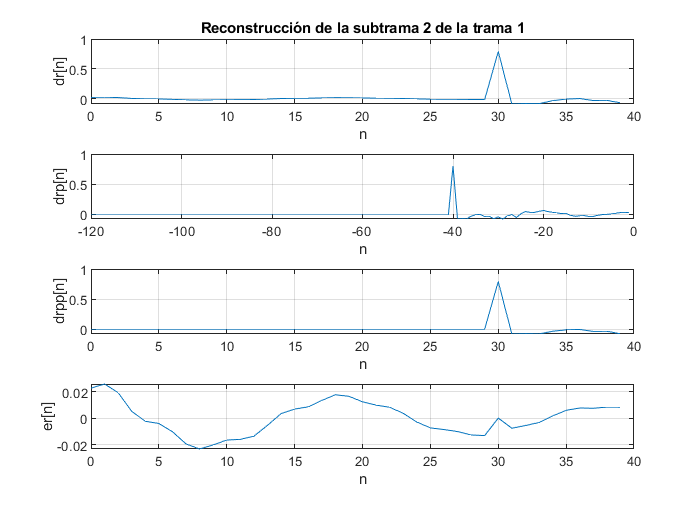

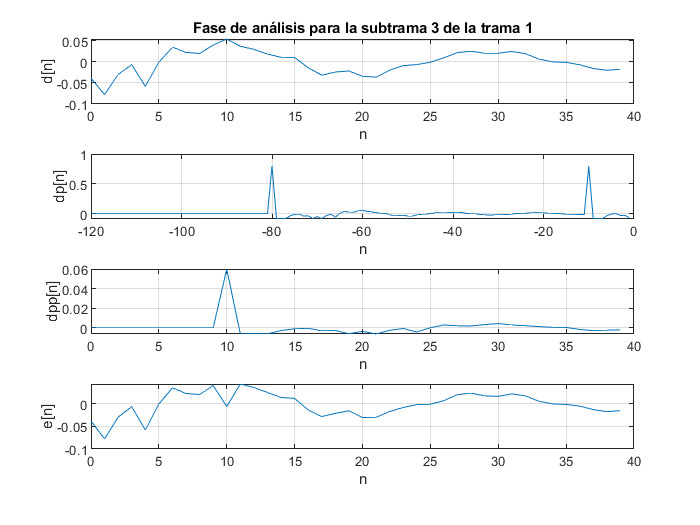

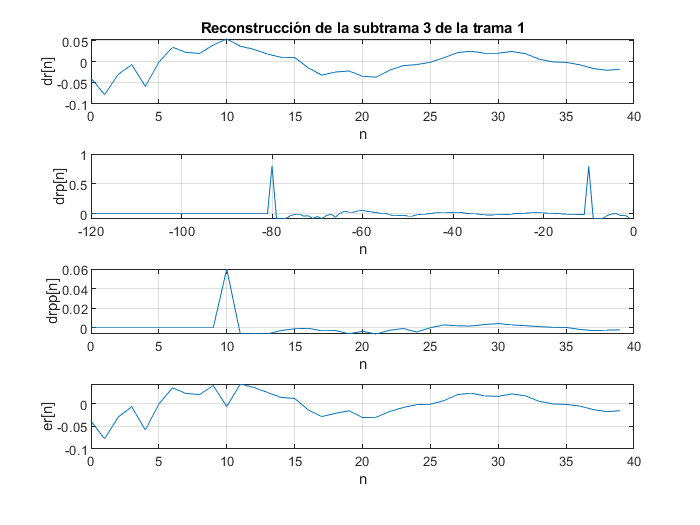

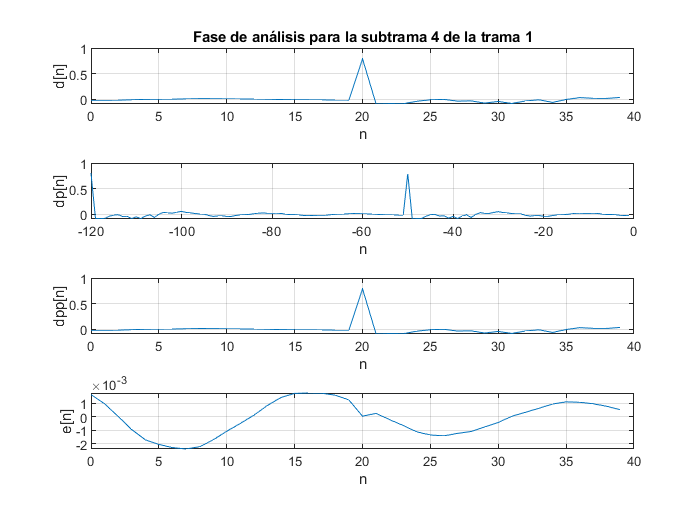

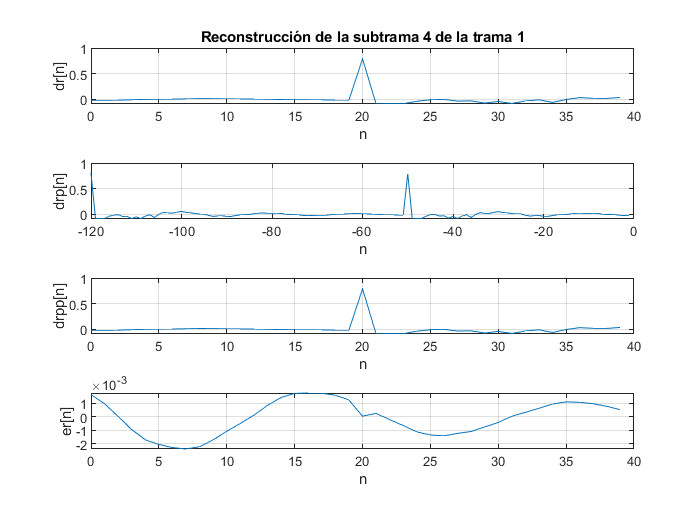

for i=1:floor(length(sn)/Lframe) 
    
    % Para cada trama:
    frame=sn(start_slice_frame:stop_slice_frame);
    Rcorr=xcorr(frame,frame);
    Rcorr=Rcorr(length(frame):length(frame)+p);
    [ak,ep,rc] =levinson(Rcorr,p);
    LPC(i, :) = ak;
    [di zi]=filter(LPC(i,:),1,frame,zi);
    dn=[dn di];
    z=[z zi];
    
    for m=1:4
        
        % Para cada subtrama:
        dactual=di(Lsubframe*(m-1)+1:Lsubframe*m); % mediria 40
        R=xcorr(dactual,dp);
        
        [Rmax, Index]=max(R(40:120));
        
        % Index es respecto a 40, hay que sumarle 39 para obtener el retardo respecto a R.
        retardo=Index+39;
        
        dpN= dp(120 - retardo + 1 : 120 - retardo + 40);
        
        bi = Rmax/(sum(dpN.^2)+eps); % se le suma al denominador eps (constante de matlab con valor ínfimo) para evitar que, en la primera subtrama de la señal, el denominador sea 0 implicando una ganancia infinita y un dpp también infinito
        
        dpp= dpN.*bi;
        ei=dactual-dpp;
        E= [E ei];
        
        if i<2
            figure;
            subplot(411),plot(0:39, dactual);xlabel('n');ylabel('d[n]'),grid,
            title("Fase de análisis para la subtrama " + m + " de la trama " + i)
            subplot(412),plot(-120:-1, dp);xlabel('n');ylabel('dp[n]'),grid,
            subplot(413),plot(0:39, dpp);xlabel('n');ylabel('dpp[n]'),grid,
            subplot(414),plot(0:39, ei);xlabel('n');ylabel('e[n]'),grid;
        end
        
        drpN= drp(120 - retardo + 1 : 120 - retardo + 40);
        drpp= drpN.*bi;
 
        drsubtrama=drpp+ei;
        dr = [dr drsubtrama];
                
        if i<2
            figure;
            subplot(411),plot(0:39, drsubtrama);xlabel('n');ylabel('dr[n]'),grid,
            title("Reconstrucción de la subtrama " + m + " de la trama " + i)
            subplot(412),plot(-120:-1, drp);xlabel('n');ylabel('drp[n]'),grid,
            subplot(413),plot(0:39, drpp);xlabel('n');ylabel('drpp[n]'),grid,
            subplot(414),plot(0:39, ei);xlabel('n');ylabel('er[n]'),grid,
        end
        
        dpanterior = dp (41:120);
        dp = [dpanterior dactual];
        
        drpanterior = drp (41:120);
        drp = [drpanterior drsubtrama];
        
    end
    
    [sri z2]=filter(1, LPC(i,:), dr(start_slice_frame:stop_slice_frame),z2);
    sr = [sr sri];
    
    start_slice_frame = start_slice_frame+Lframe;
    stop_slice_frame = stop_slice_frame+Lframe;
    
end

**FILTRO DE DEÉNFASIS:**

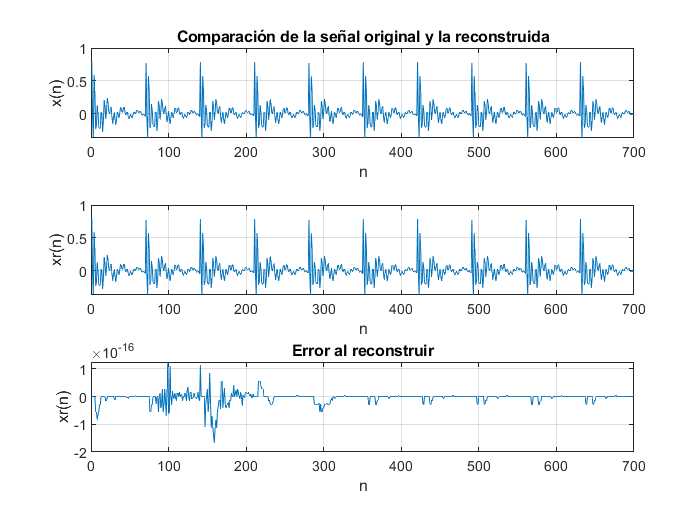

bk=[1 -0.86];
xr=filter(1,bk,sr);
a=xn(1:length(xr))-xr;
% figure
% plot(xr(1:250)),xlabel('n'),ylabel('xr(n)'),grid,

figure
subplot(311),plot(xn(1:700));xlabel('n');ylabel('x(n)'),grid,
title('Comparación de la señal original y la reconstruida')
subplot(312), plot(xr(1:700)); xlabel('n'); ylabel('xr(n)'), grid,
subplot(313),plot(a(1:700)); xlabel('n'); ylabel('xr(n)'), grid,
title('Error al reconstruir')

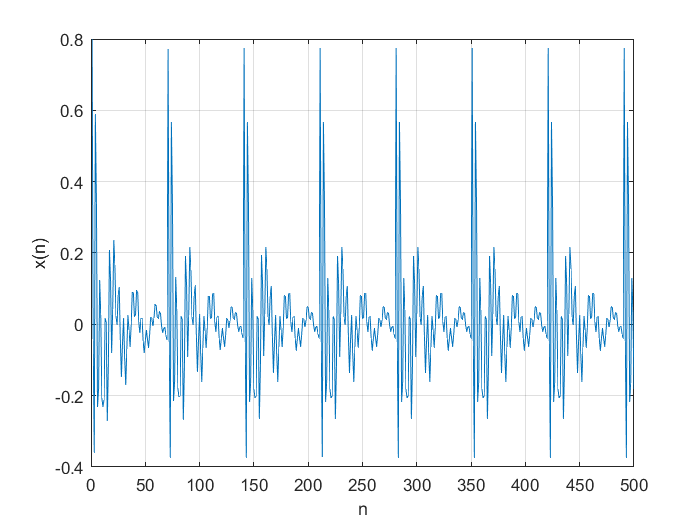

figure
plot(xn(1:500));xlabel('n');ylabel('x(n)'),grid;

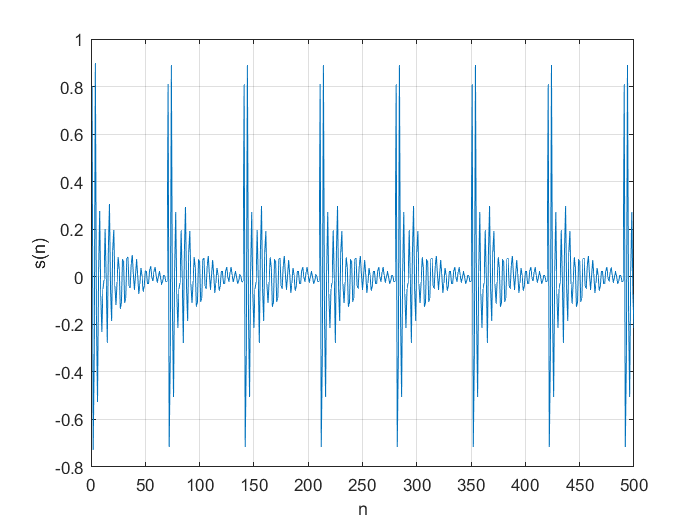


figure
plot(sn(1:500));xlabel('n');ylabel('s(n)'),grid;

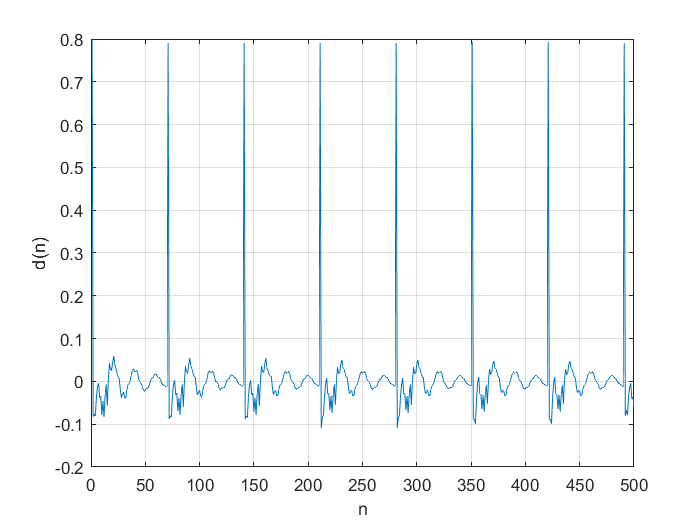


figure
plot(dn(1:500)); xlabel('n'); ylabel('d(n)'), grid;

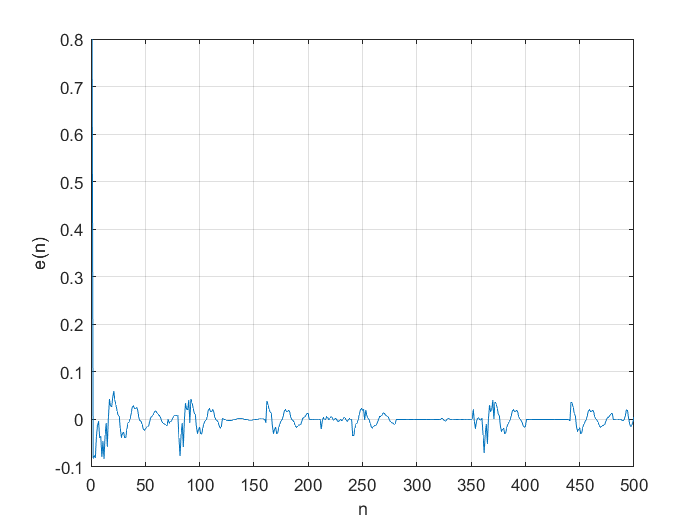


figure
plot(E(1:500));xlabel('n');ylabel('e(n)'),grid;

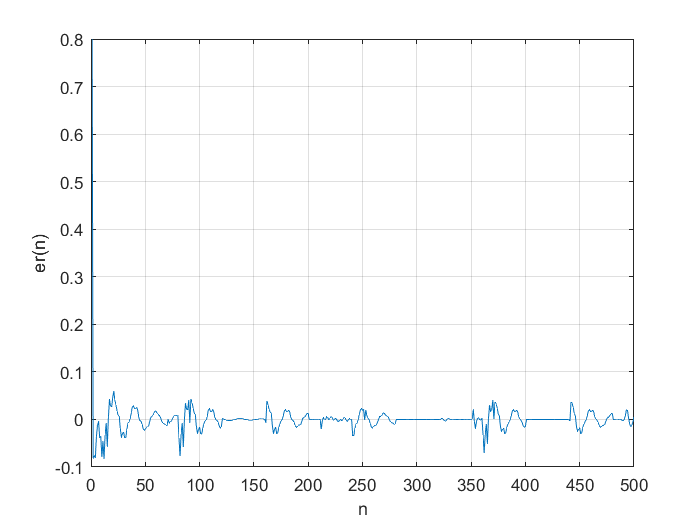


figure
plot(E(1:500));xlabel('n');ylabel('er(n)'),grid;

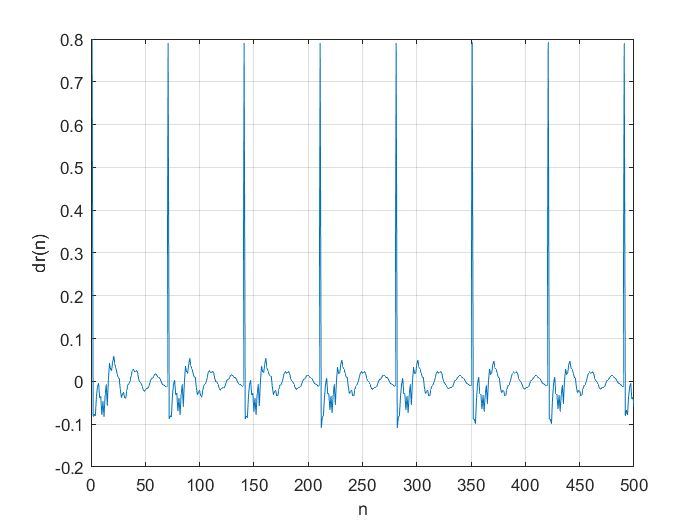


figure
plot(dr(1:500));xlabel('n');ylabel('dr(n)'),grid;

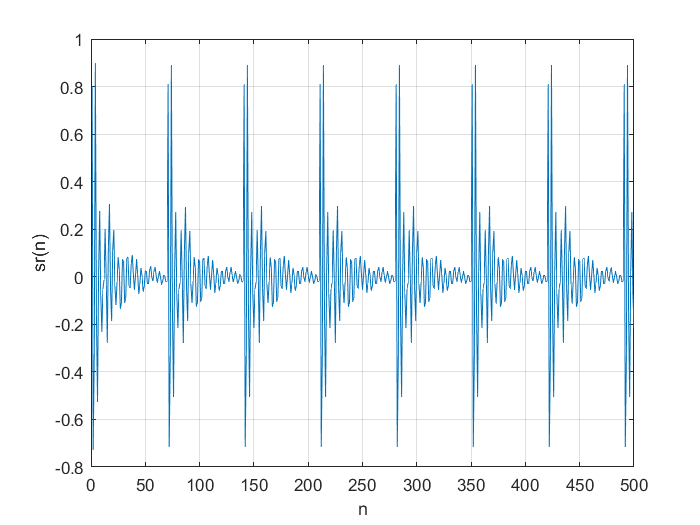


figure
plot(sr(1:500));xlabel('n');ylabel('sr(n)'),grid;

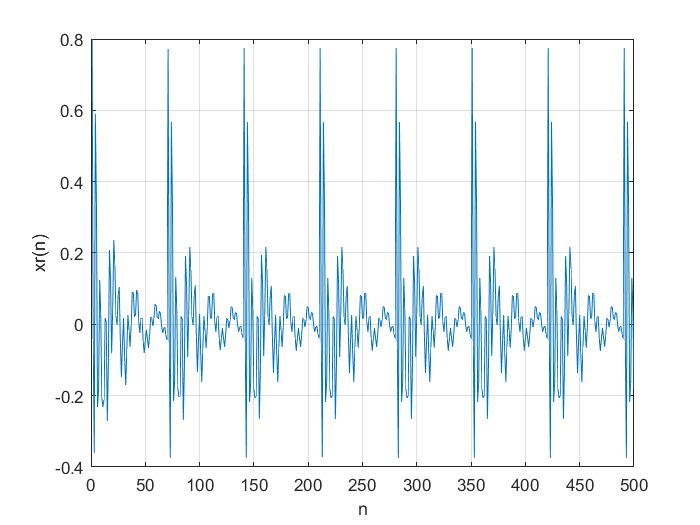


figure
plot(xr(1:500));xlabel('n');ylabel('xr(n)');grid;

**SNR:**

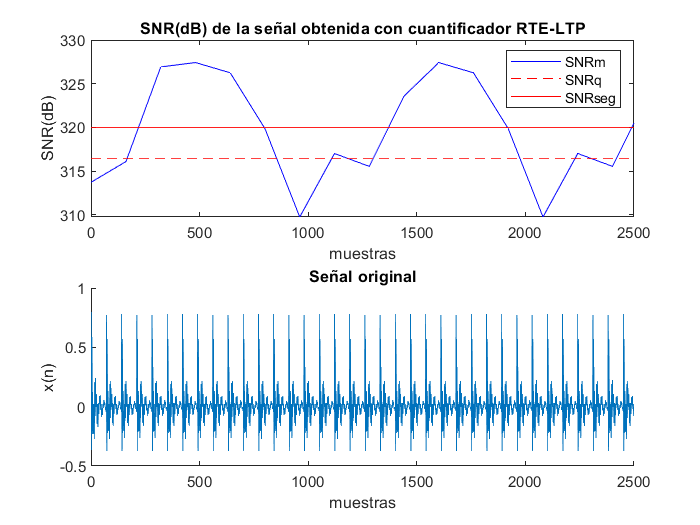

P=10;
xna=xn(1:length(xr));
SNRq = SNR(xna',xr);
[SNRseg,SNRm,m] = SNRS(xna',xr,Lframe);
figure;
%Subgrafica superior
subplot 211;
plot(m, SNRm,'b'); %SNRm riser
hold on
plot(m,ones(size(m))*(SNRq),'r--');  %SNRGlobal
plot(m,ones(size(m))*(SNRseg),'r');  %SNRSeg tread
title('SNR(dB) de la señal obtenida con cuantificador RTE-LTP');
xlabel('muestras');
ylabel('SNR(dB)');
%ylim([295 380]);
xlim([0 2500]);
legend('SNRm','SNRq','SNRseg')
%Subgrafica inferior
subplot 212;
hold on
plot(xn(1:2500)); %Senal original
title('Señal original'); xlabel('muestras'); ylabel('x(n)');
hold off